clc;
clear;
close all;
warning off;

a = 9;
b = 36;
c = b/a;

Parabola = @(x,y) x^2/sqrt(a)-y 

Parabola = function_handle with value:
    @(x,y)x^2/sqrt(a)-y


Circle = @(x,y) y^2+x*(x-(b/a)) 

Circle = function_handle with value:
    @(x,y)y^2+x*(x-(b/a))


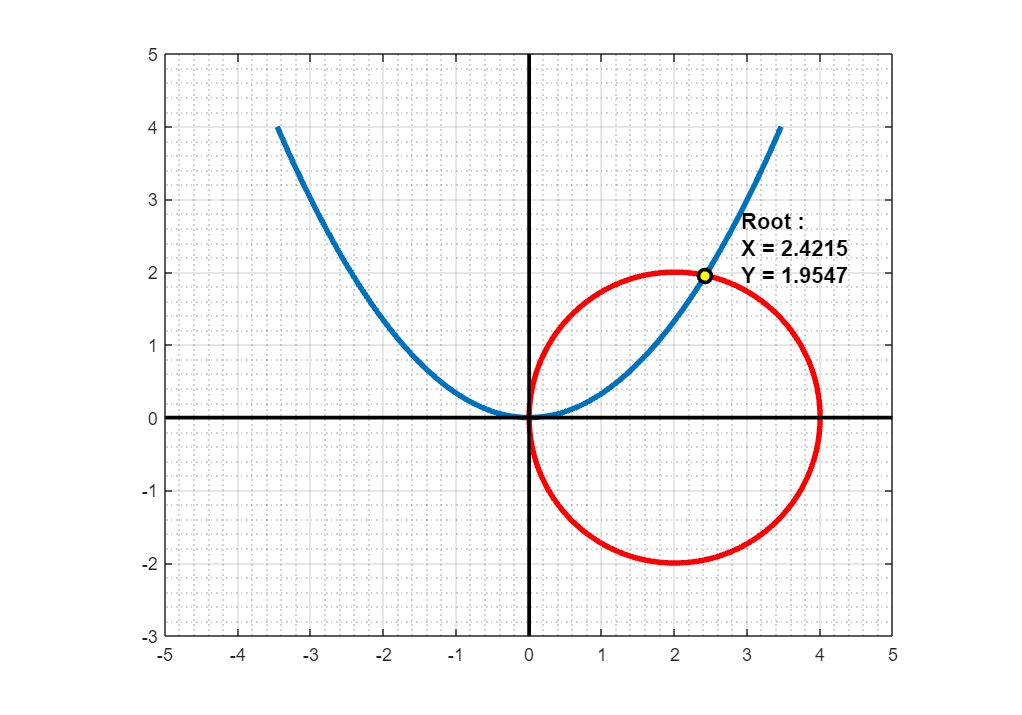

figure('Position',[50 50 1000 700]);

h1 = fimplicit(Parabola,[-c +c -c +c],'LineWidth',3);
hold on
h2 = fimplicit(Circle,[-c +c -c +c],'r','LineWidth',3);

plot([-c-1 c+1],[0 0],'k','LineWidth',2)
plot([0 0],[-c-1 c+1]+2,'k','LineWidth',2)

xlim([-c-1 +c+1])
ylim([-c +c]+1)
grid on
grid minor
axis equal
xticks(-c-1:c+1)
yticks((-c:c)+1)
x1=h1.XData;
y1=h1.YData;
x2=h2.XData;
y2=h2.YData;

[X,Y]=polyxpoly(x1,y1,x2,y2);

plot(X(2),Y(2),'ko','LineWidth',2,'MarkerSize',7,'MarkerFaceColor','y')

text(X(2)+0.2*X(2),Y(2)+0.2*Y(2),...
    {'Root : ',['X = ' num2str(X(2)) ] , ['Y = ' num2str(Y(2))]},...
    "FontSize",12,...
    "FontWeight","bold",...
    "FontName","Arial")